# Air-Fuel Ratio and Gas Temperature Increase

**Goal:** compute the amount of temperature increase due to combustion in Otto cycle

**Reference:** [EN14] Lars Eriksson, Lars Nielsen, "*Modeling and Control of Engines and Drivelines*", Wiley (2014), p.72, p.89, p.183

The temperature increase due to Otto combustion is EN14-(7.44):


$$\Delta T_{\mathrm{comb}} =\frac{q_{\mathrm{LHV}} \cdot \eta {\;}_c \left(\lambda \;\right)}{\left(\lambda \cdot \;{\mathrm{AFR}}_{\mathrm{stoich}} +1\right)\cdot c_v }$$


where $q_{\mathrm{LHV}}$ is the **lower heating value** of fuel, $\lambda \;$ is the air/fuel **equivalence ratio** (see EN14, p.72), $\eta {\;}_c \left(\lambda \;\right)=\mathrm{min}\left(1,\lambda \;\right)$ is the **combustion efficiency** (see EN-14, p.72), ${\mathrm{AFR}}_{\mathrm{stoich}}$ is the **stoichiometry** air/fuel ratio (14.7 for gasoline), $c_v$ is the **constant volume specific heat** of gas.

Note that the exhaust gas residual is ignored, i.e. $x_r =0$, in this analysis, as opposed to EN14-(7.44).

## Parameters

% lower heating value of isooctane, MJ/kg
q_LHV_MJ_perkg = paramfcn_gasoline_LHV_MJ_perkg()

q_LHV_MJ_perkg = 44.3000

q_LHV_J_perkg = q_LHV_MJ_perkg*1e+6;

% constant volume specific heat of gas in polytropic compression cycle, J/kg/K
cv_J_perkg_perK = paramfcn_cylinder_gas_Cv_comp_J_perkg_perK()

cv_J_perkg_perK = 1.1528e+03

% gasoline air/fuel ratio at stoichiometry
AFR_s = paramfcn_gasoline_AFR_stoich()

AFR_s = 14.7000


% temperature increase at stoichiometric AFR
% (just FYI)
dT_comb_stoich_K = q_LHV_J_perkg/((AFR_s + 1)*cv_J_perkg_perK)

dT_comb_stoich_K = 2.4477e+03

## Inputs

% air-to-fuel ratio (X-axis)
afr = transpose(linspace(10, 20, 200));

## Equations

% equivalence ratio, top equation at p.72 in EN14
lambda = afr/AFR_s;

% combustion efficiency, part of EN14-(4.2)
eta_c = min(1, lambda);

% temperature increase formula, EN14-(7.44) with x_r = 0
dT_comb_K = q_LHV_J_perkg .* eta_c ./ (( afr + 1 ).*cv_J_perkg_perK);

## Plot

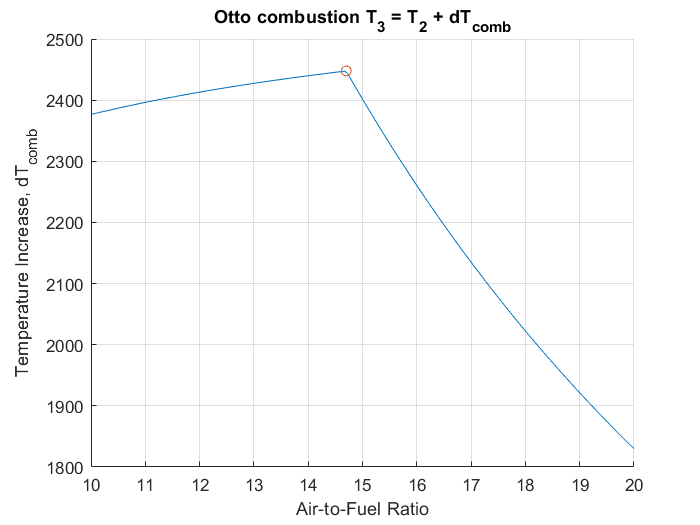

% Note that the actual gas temperature is T2 + dT_comb.
% Plot below only shows dTemp.
figure;  hold on;  grid on
plot(afr, dT_comb_K)
scatter(AFR_s, dT_comb_stoich_K)
xlabel('Air-to-Fuel Ratio')
ylabel('Temperature Increase, dT_{comb}')
title('Otto combustion T_3 = T_2 + dT_{comb}')